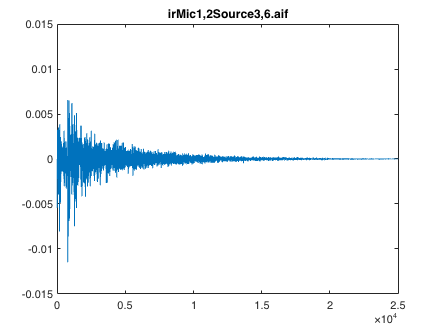

clear; clc; close all;
[IRConcertHall,Fs] = audioread('s1_r2_o.wav');
IRConcertHallMono = IRConcertHall(:,1);

[irMic12Source36,Fs] = audioread('irMic1,2Source3,6.aif');

xLimValue = [0 25000];
yLimRecorded = [-0.015 0.015];
yLimSynthesized = [0 0.1];

irMono = irMic12Source36(:,1);
L = length(irMono);
irCut = irMono(1799:L);

plot(irCut);
title("irMic1,2Source3,6.aif")
xlim(xLimValue)
ylim(yLimRecorded)

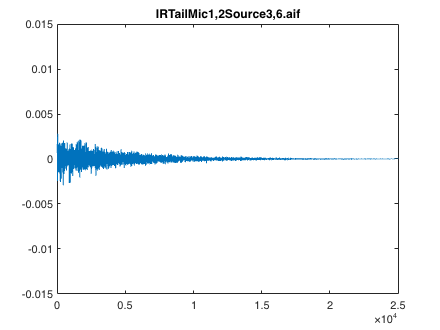

IRTail = irMono(1799+(1358*2):L);

plot(IRTail);
title("IRTailMic1,2Source3,6.aif")
xlim(xLimValue)
ylim(yLimRecorded)




[synthIRMic12Source36,Fs] = audioread('synthIRMic1,2Source3,6.wav');



[apfNoNoise,Fs] = audioread('apfNoNoise.wav');

apfCut = apfNoNoise(256:length(apfNoNoise));

convSound = conv(apfCut,synthIRMic12Source36(:,1));



ERMono = synthIRMic12Source36(:,1);
L = length(ERMono);
convER = conv(ERMono,IRTail);
ERCutNoFix = ERMono(1:1360)

ERCutNoFix =     0.3464
    0.0281
         0
         0
         0
         0
         0
         0
         0
         0


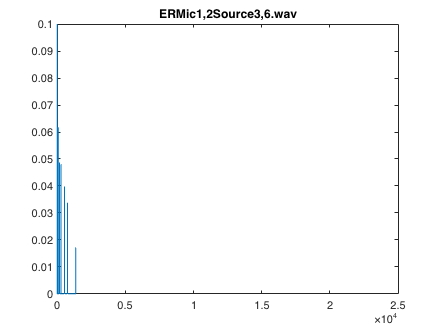

ERCut = convER(1:1360);
% Plot IR and highlight peaks (possible early reflections)
plot(ERCutNoFix);
title("ERMic1,2Source3,6.wav");
xlim(xLimValue),
ylim(yLimSynthesized);

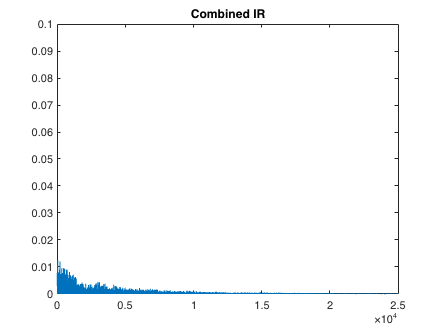

%ERInRoom = conv(ERCut,IRTail);
%plot(ERInRoom)
% Stitch together
IRCombined = [ERCut*12; IRTail*2];
plot(IRCombined);
title("Combined IR");
xlim(xLimValue);
ylim(yLimSynthesized);


%soundsc(combinedIR,Fs)

[anechoicSignal,Fs] = audioread('singing.wav');
%ancechoicSignalCut = ancechoicSignal(1:length);
convSignalFake = conv(IRCombined,anechoicSignal);
convSignalReal = conv(irCut,anechoicSignal);

soundsc(convSignalFake,Fs)

